mem = imread('Photo1.jpg');

brightness = uint8(mean(mem, 3));
red = mem(:,:,1)

red = 309×250 uint8 matrix
   245   246   248   248   250   248   249   250   250   250   248   248   250   250   251   248   252   249   251   255   255   255   250   243   236   238   244   247   246   247   251   255   250   249   248   250   254   254   253   251   251   247   242   232   227   228   234   239   240   241
   245   245   248   248   249   248   249   250   250   250   248   248   250   250   251   248   250   248   253   255   255   254   249   244   237   238   244   247   247   248   252   255   250   249   249   250   253   254   253   252   250   248   242   234   230   231   238   243   241   241
   244   245   248   248   249   247   249   249   249   249   247   248   250   250   251   248   248   248   254   255   255   249   247   247   239   241   246   249   250   251   254   255   250   247   248   249   252   253   252   251   249   247   242   233   232   233   239   244   241   242
   244   244   247   247   248   249   248   249   248   249   246   2

green = mem(:,:,2)

green = 309×250 uint8 matrix
   245   246   246   246   245   244   241   241   240   236   234   232   232   233   231   232   236   229   219   215   206   196   190   191   197   212   227   235   236   234   236   238   235   234   233   236   237   236   233   228   221   214   200   185   174   171   172   175   178   178
   245   245   246   246   244   244   241   240   240   236   234   232   232   233   231   231   235   229   221   216   205   195   190   194   198   212   227   235   237   237   237   241   237   236   236   237   239   238   233   229   222   214   201   187   177   173   176   179   179   178
   244   245   246   246   244   243   241   239   239   235   232   232   232   232   231   231   233   229   224   217   205   194   193   198   202   214   229   237   240   240   241   244   241   240   239   240   241   239   234   229   222   215   201   188   180   178   179   182   179   179
   244   244   245   245   243   242   240   239   237   235   231  

blue = mem(:,:,3)

blue = 309×250 uint8 matrix
   207   208   207   205   205   199   192   186   181   171   163   154   150   145   142   137   141   134   132   133   132   128   130   133   140   155   173   183   187   189   195   198   194   191   190   189   191   186   183   176   171   163   152   139   130   128   133   137   137   135
   207   207   208   207   204   199   192   187   181   171   163   155   150   145   142   139   140   135   134   134   131   129   130   135   141   155   173   183   188   191   196   200   195   194   192   192   192   189   183   179   172   166   155   143   135   133   139   141   138   135
   208   207   208   207   204   198   194   186   180   172   163   155   150   146   144   139   138   135   136   137   132   127   131   140   147   159   177   187   191   194   199   202   200   198   198   197   196   194   188   182   175   168   157   146   140   139   143   145   138   135
   208   208   207   206   203   198   193   186   181   172   162   

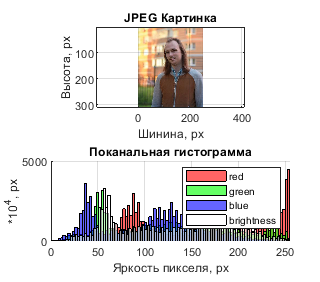


f3 = figure('Position', [50, 50, 850, 1050]);

nBins = 100;

subplot(2,1,1);
image(mem);
grid on;
axis('equal');
title('JPEG Картинка')
xlabel('Шинина, px');
ylabel('Высота, px');


subplot(2,1,2);
hold all
y1 = histogram(red, nBins, 'FaceColor', 'red');
y2 = histogram(green, nBins, 'FaceColor', 'green');
y3 = histogram(blue, nBins, 'FaceColor', 'blue');
y4 = histogram(brightness, nBins, 'FaceColor', 'white');


legend('red', 'green', 'blue', 'brightness');
xlim([0, 255]);
grid on;
title('Поканальная гистограмма')
xlabel('Яркость пикселя, px');
ylabel('*10^4');
saveas(f3, 'LAVPIC3.png')